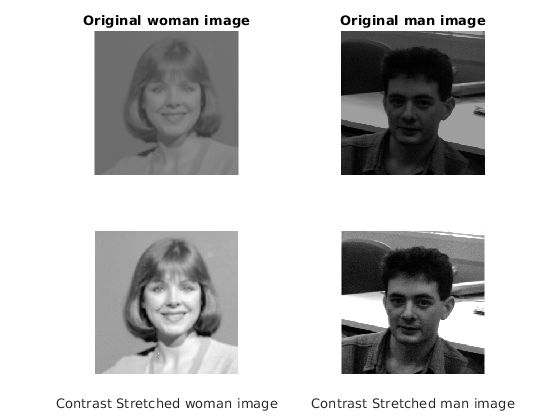

clear all;
close all;
I=imread('wom1.png');
I1=imread('man8.PNG');
subplot(2,2,1)
imshow(I)
title('Original woman image')
subplot(2,2,2)
imshow(I);
subplot(2,2,2)
imshow(I1)
title('Original man image')
CS=ContrastStretch(I);
CS1=ContrastStretch(I1);

subplot(2,2,3)
imshow(CS);
xlabel('Contrast Stretched woman image')
% the intensity values are stretched over the span of 0-255, its clearly
% shown in the histogram of woman image.
subplot(2,2,4)
imshow(CS1);
xlabel('Contrast Stretched man image')

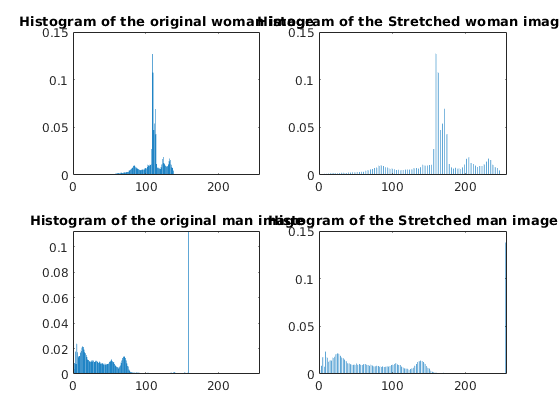

% however, the intensity values are also stretched over the span of 0-255 in man image, 
% but its not clearly shown in the histogram 
% because the original image has less intensity values about 150 .

figure
subplot(2,2,1)
bar(my_hist(I))
title('Histogram of the original woman image')
subplot(2,2,2)
bar(my_hist(CS))
title('Histogram of the Stretched woman image')
subplot(2,2,3)
bar(my_hist(I1))
title('Histogram of the original man image')
subplot(2,2,4)
bar(my_hist(CS1))
title('Histogram of the Stretched man image')